Ki = 3.33;
Kp = 5.66;
Kd = 4.14;

F = tf(1, [1, 1])

F =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



G = tf(3, [1, 4, 5, 0])

G =
 
          3
  -----------------
  s^3 + 4 s^2 + 5 s
 
Continuous-time transfer function.



Gc = tf([Kd, Kp, Ki], [1, 0])

Gc =
 
  4.14 s^2 + 5.66 s + 3.33
  ------------------------
             s
 
Continuous-time transfer function.




T = F * feedback(G * Gc, 1)

T =
 
              12.42 s^2 + 16.98 s + 9.99
  ---------------------------------------------------
  s^5 + 5 s^4 + 21.42 s^3 + 34.4 s^2 + 26.97 s + 9.99
 
Continuous-time transfer function.



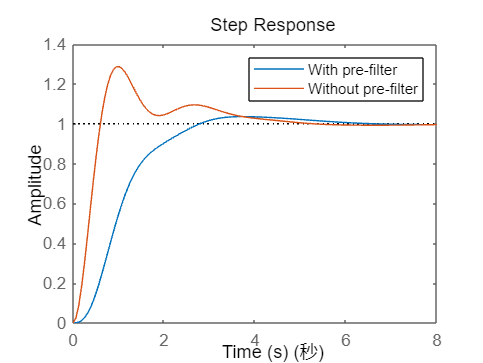


step(T, feedback(G * Gc, 1))
legend(["With pre-filter", "Without pre-filter"])
title("Step Response")
xlabel("Time (s)")
ylabel("Amplitude")

[mag, pha, w] = bode(feedback(G * Gc, 1))

mag = mag(:,:,1) =

    1.0050


mag(:,:,2) =

    1.0061


mag(:,:,3) =

    1.0083


mag(:,:,4) =

    1.0112


mag(:,:,5) =

    1.0153


mag(:,:,6) =

    1.0208


mag(:,:,7) =

    1.0283


mag(:,:,8) =

    1.0384


mag(:,:,9) =

    1.0519


mag(:,:,10) =

    1.0697


mag(:,:,11) =

    1.0924


mag(:,:,12) =

    1.1198


mag(:,:,13) =

    1.1495


mag(:,:,14) =

    1.1754


mag(:,:,15) =

    1.1895


mag(:,:,16) =

    1.1872


mag(:,:,17) =

    1.1842


mag(:,:,18) =

    1.1736


mag(:,:,19) =

    1.1600


mag(:,:,20) =

    1.1568


mag(:,:,21) =

    1.1706


mag(:,:,22) =

    1.1916


mag(:,:,23) =

    1.2221


mag(:,:,24) =

    1.2548


mag(:,:,25) =

    1.2837


mag(:,:,26) =

    1.3026


mag(:,:,27) =

    1.3064


mag(:,:,28) =

    1.2895


mag(:,:,29) =

    1.2369


mag(:,:,30) =

    1.1323


mag(:,:,31) =

    0.9733


mag(:,:,32) =

    0.7817


mag(:,:,33) =

    0.6059


mag(:,:,34) =

    0.4189


mag(:,:,35) =

    0.2909


mag(:,:,36) =

    0.20

pha = pha(:,:,1) =

   -0.0260


pha(:,:,2) =

   -0.0347


pha(:,:,3) =

   -0.0553


pha(:,:,4) =

   -0.0884


pha(:,:,5) =

   -0.1414


pha(:,:,6) =

   -0.2265


pha(:,:,7) =

   -0.3637


pha(:,:,8) =

   -0.5853


pha(:,:,9) =

   -0.9435


pha(:,:,10) =

   -1.5219


pha(:,:,11) =

   -2.4482


pha(:,:,12) =

   -3.9011


pha(:,:,13) =

   -6.0853


pha(:,:,14) =

   -9.1311


pha(:,:,15) =

  -12.9274


pha(:,:,16) =

  -17.0644


pha(:,:,17) =

  -18.2085


pha(:,:,18) =

  -21.0984


pha(:,:,19) =

  -24.9239


pha(:,:,20) =

  -28.8560


pha(:,:,21) =

  -33.4911


pha(:,:,22) =

  -37.4967


pha(:,:,23) =

  -42.6272


pha(:,:,24) =

  -48.4516


pha(:,:,25) =

  -54.9400


pha(:,:,26) =

  -61.9634


pha(:,:,27) =

  -69.2988


pha(:,:,28) =

  -77.6250


pha(:,:,29) =

  -87.9038


pha(:,:,30) =

  -99.9245


pha(:,:,31) =

 -112.8292


pha(:,:,32) =

 -125.3309


pha(:,:,33) =

 -135.5533


pha(:,:,34) =

 -145.9748


pha(:,:,35) =

 -153.2493


pha(:,:,36) =

 -158.49

w =     0.1000
    0.1100
    0.1284
    0.1499
    0.1749
    0.2042
    0.2383
    0.2781
    0.3246
    0.3789


[mag2, pha2, w2] = bode(T)

mag2 = mag2(:,:,1) =

    1.0000


mag2(:,:,2) =

    1.0000


mag2(:,:,3) =

    1.0000


mag2(:,:,4) =

    1.0000


mag2(:,:,5) =

    1.0000


mag2(:,:,6) =

    1.0000


mag2(:,:,7) =

    1.0000


mag2(:,:,8) =

    1.0000


mag2(:,:,9) =

    1.0000


mag2(:,:,10) =

    1.0000


mag2(:,:,11) =

    1.0000


mag2(:,:,12) =

    1.0000


mag2(:,:,13) =

    1.0000


mag2(:,:,14) =

    1.0000


mag2(:,:,15) =

    1.0000


mag2(:,:,16) =

    1.0000


mag2(:,:,17) =

    1.0001


mag2(:,:,18) =

    1.0001


mag2(:,:,19) =

    1.0002


mag2(:,:,20) =

    1.0003


mag2(:,:,21) =

    1.0004


mag2(:,:,22) =

    1.0005


mag2(:,:,23) =

    1.0003


mag2(:,:,24) =

    0.9991


mag2(:,:,25) =

    0.9951


mag2(:,:,26) =

    0.9846


mag2(:,:,27) =

    0.9615


mag2(:,:,28) =

    0.9194


mag2(:,:,29) =

    0.8573


mag2(:,:,30) =

    0.8373


mag2(:,:,31) =

    0.7824


mag2(:,:,32) =

    0.7055


mag2(:,:,33) =

    0.6349


mag2(:,:,34) =

    0.5739


mag2(:,:,35) =



pha2 = pha2(:,:,1) =

   -0.5730


pha2(:,:,2) =

   -0.9861


pha2(:,:,3) =

   -1.1510


pha2(:,:,4) =

   -1.3435


pha2(:,:,5) =

   -1.5681


pha2(:,:,6) =

   -1.8303


pha2(:,:,7) =

   -2.1364


pha2(:,:,8) =

   -2.4937


pha2(:,:,9) =

   -2.9108


pha2(:,:,10) =

   -3.3978


pha2(:,:,11) =

   -3.9664


pha2(:,:,12) =

   -4.6305


pha2(:,:,13) =

   -5.4062


pha2(:,:,14) =

   -5.7366


pha2(:,:,15) =

   -6.3126


pha2(:,:,16) =

   -7.3722


pha2(:,:,17) =

   -8.6118


pha2(:,:,18) =

  -10.0633


pha2(:,:,19) =

  -11.7657


pha2(:,:,20) =

  -13.7671


pha2(:,:,21) =

  -16.1283


pha2(:,:,22) =

  -18.9286


pha2(:,:,23) =

  -22.2737


pha2(:,:,24) =

  -26.3054


pha2(:,:,25) =

  -31.2030


pha2(:,:,26) =

  -37.1531


pha2(:,:,27) =

  -44.2457


pha2(:,:,28) =

  -52.3047


pha2(:,:,29) =

  -60.8343


pha2(:,:,30) =

  -63.2085


pha2(:,:,31) =

  -69.2899


pha2(:,:,32) =

  -77.4621


pha2(:,:,33) =

  -85.5705


pha2(:,:,34) =

  -94.1342


pha2(:,:,35) =



w2 =     0.0100
    0.0172
    0.0201
    0.0234
    0.0274
    0.0319
    0.0373
    0.0435
    0.0508
    0.0593
